y = yahoo;

ticker = 'AMD';
fetch(y, ticker);

from = datetime('2016-01-01');
to = datetime('2017-03-01');
data = fetch(y, ticker, 'Adj Close', from, to);

whos data

close(y);

ClosePrice = fetch(y,ticker,'Close','08/01/16','08/25/16')
d = fetch(y,ticker,'2/1/2000','2/20/2000')
v = fetch(y,ticker,Volume',now-300,now-1,'d')
cash_dividend = fetch(y,ticker,now-300,now-1,'v')

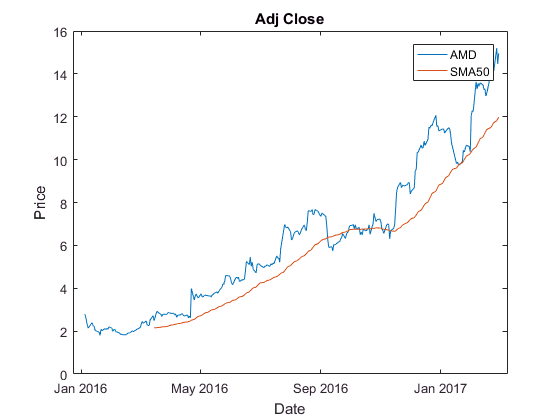


s = data(end:-1:1,2);
t = datetime(data(end:-1:1,1), 'convertfrom', 'datenum');
plot(t,s,t,sma50);

sma50 = tsmovavg(s,'s',50,1);

title('Adj Close');
xlabel('Date');
ylabel('Price');
legend(ticker, 'SMA50');

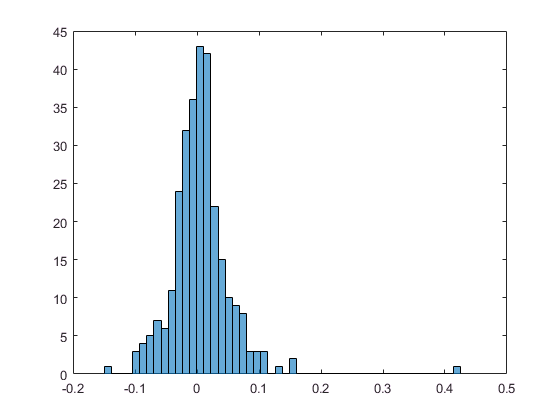


rets = tick2ret(s, t, 'continuous');
figure
histogram(rets,50);

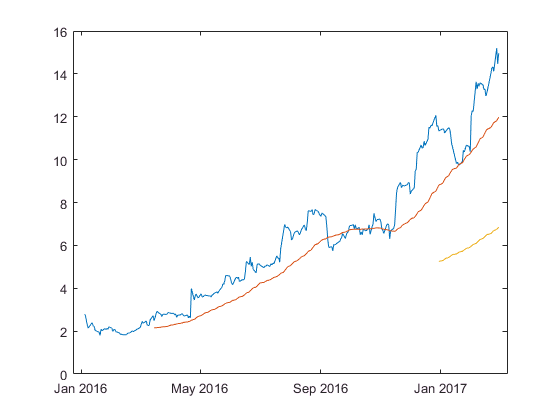

sma252 = tsmovavg(s,'s',252,1);
plot(t,s,t,sma50,t,sma252);

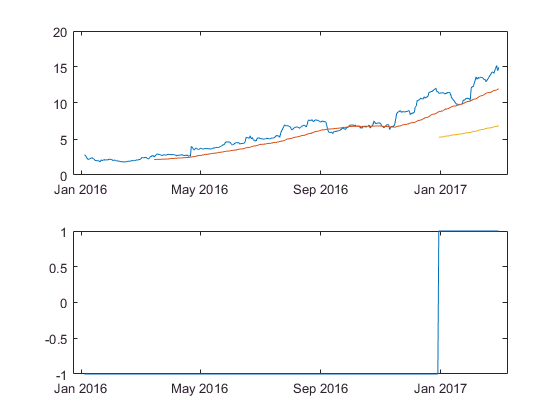

position = (sma50 > sma252) * 2 -1;
figure
subplot(2,1,1)
plot(t,s,t,sma50,t,sma252);
subplot(2,1,2)
plot(t,position);

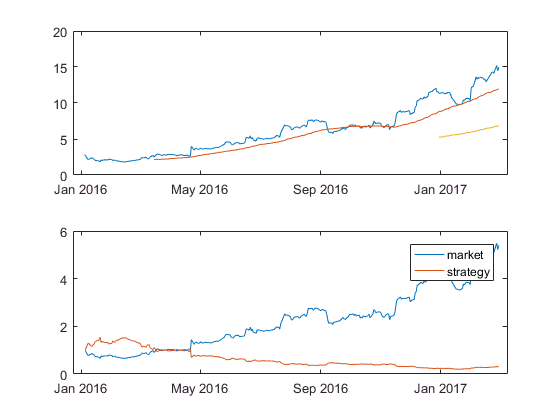

rets = tick2ret(s,t,'continuous');
strategy = position(2:end) .* rets;
cumulative_market = exp(cumsum(rets));
strategy_rets = exp(cumsum(strategy));
plot(t(2:end), cumulative_market, t(2:end), strategy_rets);
legend('market', 'strategy')

arets = mean([rets strategy]) * 252

arets =     1.4605   -1.0184


avols = std([rets strategy]) * sqrt(252)

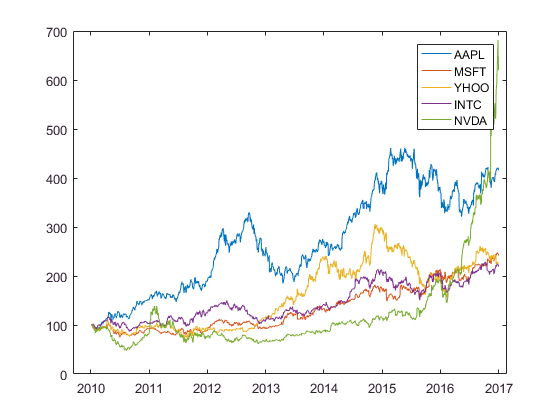

clear
from = datetime('2010-01-01');
to = datetime('2017-01-01');
tickers = ['AAPL';'MSFT';'YHOO';'INTC';'NVDA'];
y = yahoo;
for i = 1:length(tickers)
    data = fetch(y, tickers(i,:), 'Adj Close', from, to);
    prices(:,i) = data(end:-1:1, 2);
    prices_norm(:,i) = prices(:,i) / prices(1,i) * 100;
    if ~exist('t')
       t = datetime(data(end:-1:1, 1),'convertfrom','datenum');
   end
end
close(y);
figure
plot(t, prices_norm);
legend(tickers);

log_rets = tick2ret(prices, t, 'continuous');
rets = mean(log_rets) * 252;
for i = 1:length(tickers)
    disp([tickers(i,:) '=' num2str(rets(i))])
end

AAPL=0.20396
MSFT=0.12629
YHOO=0.11677
INTC=0.11219
NVDA=0.26115


weights(1:5) = 0.2;
dot(weights, rets);
cov(log_rets) * 252

ans =     0.0688    0.0240    0.0245    0.0242    0.0346
    0.0240    0.0536    0.0268    0.0305    0.0379
    0.0245    0.0268    0.0924    0.0260    0.0444
    0.0242    0.0305    0.0260    0.0550    0.0436
    0.0346    0.0379    0.0444    0.0436    0.1488



w = repmat(weights, 5, 1);
pvar = dot(weights, dot((cov(log_rets) * 252), w))

pvar = 0.0420

sqrt(pvar)

ans = 0.2051

weights = rand(1,5);
weights = weights ./ sum(weights);
w = repmat(weights, 5, 1);
pret = dot(weights, rets)

pret = 0.1659

pvar = dot(weights, dot((cov(log_rets) * 252), w))

pvar = 0.0465

count = 5000;
prets = zeros(count,1);
pvols = zeros(count,1);
for i=1:count
    weights = rand(1,5)
    weights =  weights ./ sum(weights);
    w = repmat(weights, 5, 1);
    pret(i) = dot(weights, rets)
    pvol(i) = sqrt(dot(weights, dot((cov(log_rets) * 252), w)));
end

weights =     0.0975    0.2785    0.5469    0.9575    0.9649


pret = 0.1681

weights =     0.1576    0.9706    0.9572    0.4854    0.8003


pret =     0.1681    0.1572


weights =     0.1419    0.4218    0.9157    0.7922    0.9595


pret =     0.1681    0.1572    0.1636


weights =     0.6557    0.0357    0.8491    0.9340    0.6787


pret =     0.1681    0.1572    0.1636    0.1647


weights =     0.7577    0.7431    0.3922    0.6555    0.1712


pret =     0.1681    0.1572    0.1636    0.1647    0.1516


weights =     0.7060    0.0318    0.2769    0.0462    0.0971


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821


weights =     0.8235    0.6948    0.3171    0.9502    0.0344


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448


weights =     0.4387    0.3816    0.7655    0.7952    0.1869


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422


weights =     0.4898    0.4456    0.6463    0.7094    0.7547


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669


weights =     0.2760    0.6797    0.6551    0.1626    0.1190


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416


weights =     0.4984    0.9597    0.3404    0.5853    0.2238


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483


weights =     0.7513    0.2551    0.5060    0.6991    0.8909


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791


weights =     0.9593    0.5472    0.1386    0.1493    0.2575


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779


weights =     0.8407    0.2543    0.8143    0.2435    0.9293


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845


weights =     0.3500    0.1966    0.2511    0.6160    0.4733


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687


weights =     0.3517    0.8308    0.5853    0.5497    0.9172


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689


weights =     0.2858    0.7572    0.7537    0.3804    0.5678


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577


weights =     0.0759    0.0540    0.5308    0.7792    0.9340


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751


weights =     0.1299    0.5688    0.4694    0.0119    0.3371


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599


weights =     0.1622    0.7943    0.3112    0.5285    0.1656


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388


weights =     0.6020    0.2630    0.6541    0.6892    0.7482


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708


weights =     0.4505    0.0838    0.2290    0.9133    0.1524


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484


weights =     0.8258    0.5383    0.9961    0.0782    0.4427


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656


weights =     0.1067    0.9619    0.0046    0.7749    0.8173


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666


weights =     0.8687    0.0844    0.3998    0.2599    0.8001


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959


weights =     0.4314    0.9106    0.1818    0.2638    0.1455


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510


weights =     0.1361    0.8693    0.5797    0.5499    0.1450


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337


weights =     0.8530    0.6221    0.3510    0.5132    0.4018


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664


weights =     0.0760    0.2399    0.1233    0.1839    0.2400


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663


weights =     0.4173    0.0497    0.9027    0.9448    0.4909


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536


weights =     0.4893    0.3377    0.9001    0.3692    0.1112


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441


weights =     0.7803    0.3897    0.2417    0.4039    0.0965


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606


weights =     0.1320    0.9421    0.9561    0.5752    0.0598


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267


weights =     0.2348    0.3532    0.8212    0.0154    0.0430


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372


weights =     0.1690    0.6491    0.7317    0.6477    0.4509


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481


weights =     0.5470    0.2963    0.7447    0.1890    0.6868


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772


weights =     0.1835    0.3685    0.6256    0.7802    0.0811


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303


weights =     0.9294    0.7757    0.4868    0.4359    0.4468


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659


weights =     0.3063    0.5085    0.5108    0.8176    0.7948


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653


weights =     0.6443    0.3786    0.8116    0.5328    0.3507


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565


weights =     0.9390    0.8759    0.5502    0.6225    0.5870


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649


weights =     0.2077    0.3012    0.4709    0.2305    0.8443


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858


weights =     0.1948    0.2259    0.1707    0.2277    0.4357


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813


weights =     0.3111    0.9234    0.4302    0.1848    0.9049


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769


weights =     0.9797    0.4389    0.1111    0.2581    0.4087


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839


weights =     0.5949    0.2622    0.6028    0.7112    0.2217


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515


weights =     0.1174    0.2967    0.3188    0.4242    0.5079


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675


weights =     0.0855    0.2625    0.8010    0.0292    0.9289


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851


weights =     0.7303    0.4886    0.5785    0.2373    0.4588


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703


weights =     0.9631    0.5468    0.5211    0.2316    0.4889


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6241    0.6791    0.3955    0.3674    0.9880


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0377    0.8852    0.9133    0.7962    0.0987


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2619    0.3354    0.6797    0.1366    0.7212


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1068    0.6538    0.4942    0.7791    0.7150


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9037    0.8909    0.3342    0.6987    0.1978


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0305    0.7441    0.5000    0.4799    0.9047


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6099    0.6177    0.8594    0.8055    0.5767


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1829    0.2399    0.8865    0.0287    0.4899


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1679    0.9787    0.7127    0.5005    0.4711


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0596    0.6820    0.0424    0.0714    0.5216


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0967    0.8181    0.8175    0.7224    0.1499


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6596    0.5186    0.9730    0.6490    0.8003


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4538    0.4324    0.8253    0.0835    0.1332


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1734    0.3909    0.8314    0.8034    0.0605


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3993    0.5269    0.4168    0.6569    0.6280


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2920    0.4317    0.0155    0.9841    0.1672


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1062    0.3724    0.1981    0.4897    0.3395


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9516    0.9203    0.0527    0.7379    0.2691


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4228    0.5479    0.9427    0.4177    0.9831


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3015    0.7011    0.6663    0.5391    0.6981


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6665    0.1781    0.1280    0.9991    0.1711


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0326    0.5612    0.8819    0.6692    0.1904


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3689    0.4607    0.9816    0.1564    0.8555


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6448    0.3763    0.1909    0.4283    0.4820


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1206    0.5895    0.2262    0.3846    0.5830


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2518    0.2904    0.6171    0.2653    0.8244


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9827    0.7302    0.3439    0.5841    0.1078


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9063    0.8797    0.8178    0.2607    0.5944


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0225    0.4253    0.3127    0.1615    0.1788


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4229    0.0942    0.5985    0.4709    0.6959


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6999    0.6385    0.0336    0.0688    0.3196


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5309    0.6544    0.4076    0.8200    0.7184


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9686    0.5313    0.3251    0.1056    0.6110


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7788    0.4235    0.0908    0.2665    0.1537


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2810    0.4401    0.5271    0.4574    0.8754


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5181    0.9436    0.6377    0.9577    0.2407


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6761    0.2891    0.6718    0.6951    0.0680


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2548    0.2240    0.6678    0.8444    0.3445


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7805    0.6753    0.0067    0.6022    0.3868


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9160    0.0012    0.4624    0.4243    0.4609


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7702    0.3225    0.7847    0.4714    0.0358


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1759    0.7218    0.4735    0.1527    0.3411


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6074    0.1917    0.7384    0.2428    0.9174


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2691    0.7655    0.1887    0.2875    0.0911


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5762    0.6834    0.5466    0.4257    0.6444


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6476    0.6790    0.6358    0.9452    0.2089


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7093    0.2362    0.1194    0.6073    0.4501


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4587    0.6619    0.7703    0.3502    0.6620


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4162    0.8419    0.8329    0.2564    0.6135


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5822    0.5407    0.8699    0.2648    0.3181


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1192    0.9398    0.6456    0.4795    0.6393


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5447    0.6473    0.5439    0.7210    0.5225


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9937    0.2187    0.1058    0.1097    0.0636


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4046    0.4484    0.3658    0.7635    0.6279


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7720    0.9329    0.9727    0.1920    0.1389


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6963    0.0938    0.5254    0.5303    0.8611


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4849    0.3935    0.6714    0.7413    0.5201


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3477    0.1500    0.5861    0.2621    0.0445


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7549    0.2428    0.4424    0.6878    0.3592


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7363    0.3947    0.6834    0.7040    0.4423


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0196    0.3309    0.4243    0.2703    0.1971


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8217    0.4299    0.8878    0.3912    0.7691


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3968    0.8085    0.7551    0.3774    0.2160


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7904    0.9493    0.3276    0.6713    0.4386


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8335    0.7689    0.1673    0.8620    0.9899


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5144    0.8843    0.5880    0.1548    0.1999


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4070    0.7487    0.8256    0.7900    0.3185


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5341    0.0900    0.1117    0.1363    0.6787


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4952    0.1897    0.4950    0.1476    0.0550


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8507    0.5606    0.9296    0.6967    0.5828


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8154    0.8790    0.9889    0.0005    0.8654


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6126    0.9900    0.5277    0.4795    0.8013


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2278    0.4981    0.9009    0.5747    0.8452


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7386    0.5860    0.2467    0.6664    0.0835


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6260    0.6609    0.7298    0.8908    0.9823


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7690    0.5814    0.9283    0.5801    0.0170


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1209    0.8627    0.4843    0.8449    0.2094


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5523    0.6299    0.0320    0.6147    0.3624


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0495    0.4896    0.1925    0.1231    0.2055


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1465    0.1891    0.0427    0.6352    0.2819


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5386    0.6952    0.4991    0.5358    0.4452


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1239    0.4904    0.8530    0.8739    0.2703


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2085    0.5650    0.6403    0.4170    0.2060


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9479    0.0821    0.1057    0.1420    0.1665


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6210    0.5737    0.0521    0.9312    0.7287


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7378    0.0634    0.8604    0.9344    0.9844


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8589    0.7856    0.5134    0.1776    0.3986


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1339    0.0309    0.9391    0.3013    0.2955


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3329    0.4671    0.6482    0.0252    0.8422


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5590    0.8541    0.3479    0.4460    0.0542


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1771    0.6628    0.3308    0.8985    0.1182


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9884    0.5400    0.7069    0.9995    0.2878


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4145    0.4648    0.7640    0.8182    0.1002


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1781    0.3596    0.0567    0.5219    0.3358


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1757    0.2089    0.9052    0.6754    0.4685


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9121    0.1040    0.7455    0.7363    0.5619


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1842    0.5972    0.2999    0.1341    0.2126


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8949    0.0715    0.2425    0.0538    0.4417


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0133    0.8972    0.1967    0.0934    0.3074


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4561    0.1017    0.9954    0.3321    0.2973


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0620    0.2982    0.0464    0.5054    0.7614


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6311    0.0899    0.0809    0.7772    0.9051


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5338    0.1092    0.8258    0.3381    0.2940


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7463    0.0103    0.0484    0.6679    0.6035


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5261    0.7297    0.7073    0.7814    0.2880


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6925    0.5567    0.3965    0.0616    0.7802


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3376    0.6079    0.7413    0.1048    0.1279


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5495    0.4852    0.8905    0.7990    0.7343


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0513    0.0729    0.0885    0.7984    0.9430


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6837    0.1321    0.7227    0.1104    0.1175


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6407    0.3288    0.6538    0.7491    0.5832


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7400    0.2348    0.7350    0.9706    0.8669


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0862    0.3664    0.3692    0.6850    0.5979


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7894    0.3677    0.2060    0.0867    0.7719


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2057    0.3883    0.5518    0.2290    0.6419


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4845    0.1518    0.7819    0.1006    0.2941


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2374    0.5309    0.0915    0.4053    0.1048


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1123    0.7844    0.2916    0.6035    0.9644


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4325    0.6948    0.7581    0.4326    0.6555


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1098    0.9338    0.1875    0.2662    0.7978


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4876    0.7690    0.3960    0.2729    0.0372


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6733    0.4296    0.4517    0.6099    0.0594


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3158    0.7727    0.6964    0.1253    0.1302


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0924    0.0078    0.4231    0.6556    0.7229


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5312    0.1088    0.6318    0.1265    0.1343


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0986    0.1420    0.1683    0.1962    0.3175


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3164    0.2176    0.2510    0.8929    0.7032


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5557    0.1844    0.2120    0.0773    0.9138


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7067    0.5578    0.3134    0.1662    0.6225


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9879    0.1704    0.2578    0.3968    0.0740


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6841    0.4024    0.9828    0.4022    0.6207


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1544    0.3813    0.1611    0.7581    0.8711


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3508    0.6855    0.2941    0.5306    0.8324


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5975    0.3353    0.2992    0.4526    0.4226


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3596    0.5583    0.7425    0.4243    0.4294


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1249    0.0244    0.2902    0.3175    0.6537


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9569    0.9357    0.4579    0.2405    0.7639


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7593    0.7406    0.7437    0.1059    0.6816


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4633    0.2122    0.0985    0.8236    0.1750


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1636    0.6660    0.8944    0.5166    0.7027


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1536    0.9535    0.5409    0.6797    0.0366


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8092    0.7486    0.1202    0.5250    0.3258


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5464    0.3989    0.4151    0.1807    0.2554


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0205    0.9237    0.6537    0.9326    0.1635


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9211    0.7947    0.5774    0.4400    0.2576


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7519    0.2287    0.0642    0.7673    0.6712


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7152    0.6421    0.4190    0.3908    0.8161


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3174    0.8145    0.7891    0.8523    0.5056


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6357    0.9509    0.4440    0.0600    0.8667


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6312    0.3551    0.9970    0.2242    0.6525


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6050    0.3872    0.1422    0.0251    0.4211


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1841    0.7258    0.3704    0.8416    0.7342


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5710    0.1769    0.9574    0.2653    0.9246


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2238    0.3736    0.0875    0.6401    0.1806


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0451    0.7232    0.3474    0.6606    0.3839


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6273    0.0216    0.9106    0.8006    0.7458


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8131    0.3833    0.6173    0.5755    0.5301


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2751    0.2486    0.4516    0.2277    0.8044


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9861    0.0300    0.5357    0.0871    0.8021


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9891    0.0669    0.9394    0.0182    0.6838


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7837    0.5341    0.8854    0.8990    0.6259


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1379    0.2178    0.1821    0.0418    0.1069


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6164    0.9397    0.3545    0.4106    0.9843


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9456    0.6766    0.9883    0.7668    0.3367


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6624    0.2442    0.2955    0.6802    0.5278


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4116    0.6026    0.7505    0.5835    0.5518


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5836    0.5118    0.0826    0.7196    0.9962


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3545    0.9713    0.3464    0.8865    0.4547


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4134    0.2177    0.1257    0.3089    0.7261


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7829    0.6938    0.0098    0.8432    0.9223


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7710    0.0427    0.3782    0.7043    0.7295


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2243    0.2691    0.6730    0.4775    0.6237


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2364    0.1771    0.8296    0.7669    0.9345


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1079    0.1822    0.0991    0.4898    0.1932


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8959    0.0991    0.0442    0.5573    0.7725


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3119    0.1790    0.3390    0.2101    0.5102


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9064    0.6289    0.1015    0.3909    0.0546


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5013    0.4317    0.9976    0.8116    0.4857


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8944    0.1375    0.3900    0.9274    0.9175


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7136    0.6183    0.3433    0.9360    0.1248


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7306    0.6465    0.8332    0.3983    0.7498


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8352    0.3225    0.5523    0.9791    0.5493


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3304    0.6195    0.3606    0.7565    0.4139


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4923    0.6947    0.9727    0.3278    0.8378


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7391    0.9542    0.0319    0.3569    0.6627


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2815    0.2304    0.7111    0.6246    0.5906


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6604    0.0476    0.3488    0.4513    0.2409


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7150    0.8562    0.2815    0.7311    0.1378


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8367    0.1386    0.5882    0.3662    0.8068


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5038    0.4896    0.8770    0.3531    0.4494


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9635    0.0423    0.9730    0.1892    0.6671


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5864    0.6751    0.3610    0.6203    0.8112


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0193    0.0839    0.9748    0.6513    0.2312


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4035    0.1220    0.2684    0.2578    0.3317


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1522    0.3480    0.1217    0.8842    0.0943


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9300    0.3990    0.0474    0.3424    0.7360


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7947    0.5449    0.6862    0.8936    0.0548


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3037    0.0462    0.1955    0.7202    0.7218


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8778    0.5824    0.0707    0.9227    0.8004


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2859    0.5437    0.9848    0.7157    0.8390


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4333    0.4706    0.5607    0.2691    0.7490


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5039    0.6468    0.3077    0.1387    0.4756


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3625    0.7881    0.7803    0.6685    0.1335


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0216    0.5598    0.3008    0.9394    0.9809


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2866    0.8008    0.8961    0.5975    0.8840


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9437    0.5492    0.7284    0.5768    0.0259


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4465    0.6463    0.5212    0.3723    0.9371


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8295    0.8491    0.3725    0.5932    0.8726


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9335    0.6685    0.2068    0.6539    0.0721


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4067    0.6669    0.9337    0.8110    0.4845


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7567    0.4170    0.9718    0.9880    0.8641


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3889    0.4547    0.2467    0.7844    0.8828


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9137    0.5583    0.5989    0.1489    0.8997


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4504    0.2057    0.8997    0.7626    0.8825


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2850    0.6732    0.6643    0.1228    0.4073


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2753    0.7167    0.2834    0.8962    0.8266


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3900    0.4979    0.6948    0.8344    0.6096


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5747    0.3260    0.4564    0.7138    0.8844


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7209    0.0186    0.6748    0.4385    0.4378


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1170    0.8147    0.3249    0.2462    0.3427


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3757    0.5466    0.5619    0.3958    0.3981


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5154    0.6575    0.9509    0.7223    0.4001


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8319    0.1343    0.0605    0.0842    0.1639


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3242    0.3017    0.0117    0.5399    0.0954


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1465    0.6311    0.8593    0.9742    0.5708


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9969    0.5535    0.5155    0.3307    0.4300


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4918    0.0710    0.8877    0.0646    0.4362


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8266    0.3945    0.6135    0.8186    0.8862


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9311    0.1908    0.2586    0.8979    0.5934


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5038    0.6128    0.8194    0.5319    0.2021


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4539    0.4279    0.9661    0.6201    0.6954


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7202    0.3469    0.5170    0.5567    0.1565


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5621    0.6948    0.4265    0.8363    0.7314


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3600    0.4542    0.3864    0.7756    0.7343


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4303    0.6938    0.9452    0.7842    0.7056


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1093    0.3899    0.5909    0.4594    0.0503


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2287    0.8342    0.0156    0.8637    0.0781


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6690    0.5002    0.2180    0.5716    0.1222


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6712    0.5996    0.0560    0.0563    0.1525


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0196    0.4352    0.8322    0.6174    0.5201


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8639    0.0977    0.9081    0.1080    0.5170


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1432    0.5594    0.0046    0.7667    0.8487


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9168    0.9870    0.5051    0.2714    0.1008


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5078    0.5856    0.7629    0.0830    0.6616


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5170    0.1710    0.9386    0.5905    0.4406


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9419    0.6559    0.4519    0.8397    0.5326


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5539    0.6801    0.3672    0.2393    0.5789


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8669    0.4068    0.1126    0.4438    0.3002


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4014    0.8334    0.4036    0.3902    0.3604


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1403    0.2601    0.0868    0.4294    0.2573


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2976    0.4249    0.1192    0.4951    0.7064


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2436    0.7851    0.0741    0.3939    0.0034


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2207    0.0013    0.1892    0.1425    0.2681


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1749    0.1386    0.5989    0.9011    0.9394


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2212    0.4827    0.3760    0.5238    0.2649


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0684    0.4363    0.1739    0.0261    0.9547


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4306    0.9616    0.7624    0.0073    0.6800


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7060    0.6451    0.5523    0.2181    0.7724


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2280    0.3709    0.8909    0.8564    0.4024


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3180    0.6086    0.9102    0.9091    0.5916


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3326    0.8531    0.4424    0.9044    0.0332


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5324    0.7165    0.1793    0.3365    0.1877


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3219    0.4039    0.5486    0.0487    0.5527


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2748    0.2415    0.2431    0.1542    0.9564


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9357    0.8187    0.7283    0.1758    0.3604


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1888    0.0012    0.3164    0.6996    0.6253


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5431    0.4390    0.2874    0.5017    0.7615


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7624    0.5761    0.7477    0.6455    0.1232


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5044    0.3473    0.0921    0.1478    0.1982


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6723    0.4315    0.6944    0.2568    0.0098


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5323    0.2794    0.9462    0.9064    0.3927


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0249    0.6714    0.8372    0.9715    0.0569


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4503    0.5825    0.6866    0.7194    0.6500


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7269    0.3738    0.5816    0.1161    0.0577


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9798    0.2848    0.5950    0.9622    0.1858


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1930    0.3416    0.9329    0.3907    0.2732


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1519    0.3971    0.3747    0.1311    0.4350


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0915    0.6146    0.0110    0.5733    0.7897


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2354    0.4480    0.5694    0.0614    0.4963


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6423    0.2213    0.8371    0.9711    0.8464


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5060    0.2789    0.7466    0.2369    0.9573


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6203    0.6003    0.1726    0.0903    0.2553


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8586    0.9111    0.6996    0.7252    0.2299


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5761    0.8106    0.4038    0.9884    0.0900


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3209    0.5114    0.0606    0.7257    0.5566


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5294    0.8300    0.8588    0.7890    0.3178


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4522    0.7522    0.1099    0.1097    0.2699


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5246    0.9727    0.7104    0.3119    0.2915


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8504    0.9116    0.6393    0.2554    0.0887


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8383    0.5847    0.9481    0.0610    0.5846


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2851    0.8277    0.1910    0.4425    0.3934


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8266    0.6769    0.2076    0.3181    0.1338


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6715    0.5710    0.1698    0.1477    0.4761


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9081    0.5522    0.0329    0.0539    0.8051


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4514    0.3826    0.7896    0.3643    0.5323


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7117    0.8715    0.3287    0.6501    0.9748


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0760    0.5870    0.4139    0.3091    0.2638


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7588    0.9952    0.1866    0.7811    0.1958


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9924    0.8023    0.4242    0.7289    0.4984


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8090    0.3565    0.0732    0.5910    0.9102


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1938    0.4324    0.7492    0.0392    0.9463


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7637    0.5588    0.1838    0.4979    0.5178


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9942    0.8549    0.9624    0.6789    0.4035


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9350    0.4795    0.2318    0.3963    0.7051


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5586    0.7566    0.9955    0.9624    0.5351


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9639    0.1156    0.0514    0.3043    0.5802


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5310    0.9012    0.5406    0.4320    0.5427


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7124    0.0167    0.8009    0.1425    0.4785


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2568    0.3691    0.6618    0.1696    0.2788


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1982    0.1951    0.3268    0.8803    0.4711


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4040    0.1792    0.9689    0.4075    0.8445


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6153    0.3766    0.8772    0.7849    0.4650


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8140    0.8984    0.4292    0.3343    0.5966


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9020    0.7021    0.3775    0.7350    0.9541


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5428    0.5401    0.3111    0.0712    0.1820


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0930    0.4635    0.0093    0.9150    0.6427


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0014    0.0304    0.2085    0.4550    0.1273


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0086    0.7271    0.3541    0.7804    0.4367


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4366    0.0492    0.0496    0.0911    0.5940


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2411    0.8414    0.8572    0.9636    0.4889


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2203    0.2262    0.5368    0.7621    0.3476


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4612    0.6393    0.9173    0.1616    0.7156


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5777    0.4333    0.8842    0.3931    0.1790


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6333    0.6240    0.3279    0.8030    0.9995


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9810    0.1270    0.2322    0.0236    0.6074


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1108    0.4075    0.8841    0.5481    0.3690


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2083    0.4409    0.9562    0.1240    0.4708


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8569    0.0434    0.6916    0.9790    0.2833


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1338    0.6853    0.9095    0.6109    0.9000


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1934    0.7544    0.3463    0.4186    0.1557


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8190    0.6249    0.7386    0.8051    0.0672


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9508    0.4976    0.7551    0.7424    0.8311


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1565    0.4573    0.6181    0.9322    0.8351


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8954    0.5825    0.5827    0.8549    0.0349


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8854    0.4077    0.0364    0.7461    0.1548


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1439    0.6060    0.2545    0.3242    0.4018


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4064    0.3862    0.6098    0.1669    0.1881


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0946    0.3232    0.7696    0.2341    0.7404


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6928    0.8241    0.8280    0.2934    0.3094


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5230    0.3253    0.8318    0.8103    0.5570


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2630    0.6806    0.2337    0.4564    0.3846


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5386    0.9917    0.7552    0.9805    0.2348


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5286    0.0514    0.7569    0.6020    0.8572


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9883    0.9295    0.4095    0.0003    0.5409


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2077    0.2193    0.3258    0.0959    0.7475


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7485    0.5433    0.3381    0.8323    0.5526


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9575    0.8928    0.3565    0.5464    0.3467


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6228    0.7966    0.7459    0.1255    0.8224


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0252    0.4144    0.7314    0.7814    0.3673


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7449    0.8923    0.2426    0.1296    0.2251


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3500    0.2871    0.9275    0.0513    0.5927


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1629    0.8384    0.1676    0.5022    0.9993


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3554    0.0471    0.2137    0.3978    0.3337


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2296    0.9361    0.6832    0.9621    0.4380


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9403    0.0058    0.6103    0.8011    0.2330


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9325    0.7633    0.8264    0.5735    0.7926


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3290    0.2235    0.3124    0.5845    0.8299


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2905    0.4026    0.8621    0.6147    0.9912


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2037    0.8272    0.6759    0.2489    0.4758


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3991    0.5994    0.8005    0.1051    0.8214


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8411    0.3545    0.4301    0.5722    0.7008


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7425    0.7579    0.3891    0.4293    0.9563


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5730    0.8497    0.2763    0.6223    0.5884


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9635    0.0859    0.5005    0.5216    0.0902


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9047    0.8844    0.4390    0.7817    0.1485


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6198    0.2606    0.4457    0.8440    0.1962


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3039    0.4833    0.3378    0.7985    0.9875


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1590    0.2369    0.7022    0.3755    0.9737


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9723    0.6437    0.8601    0.4019    0.6319


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9852    0.5595    0.9336    0.7203    0.4840


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6390    0.8876    0.1987    0.3954    0.9922


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4024    0.6589    0.9013    0.9954    0.6532


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1084    0.0361    0.6181    0.5671    0.9620


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7461    0.6625    0.5233    0.2599    0.9620


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5402    0.0303    0.6963    0.5197    0.0590


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8900    0.3302    0.2297    0.1139    0.3109


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2284    0.6520    0.0662    0.2754    0.2818


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8801    0.4443    0.7559    0.6033    0.7833


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1139    0.9786    0.8486    0.0506    0.4662


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3257    0.6302    0.2303    0.5799    0.6032


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5999    0.4484    0.0354    0.5138    0.4077


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1080    0.4599    0.4509    0.5511    0.8054


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7009    0.8722    0.0522    0.2197    0.4596


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9585    0.7900    0.4519    0.3334    0.0591


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7409    0.5068    0.1999    0.4272    0.1687


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7517    0.3684    0.9418    0.0172    0.8291


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6266    0.5387    0.6505    0.7266    0.0945


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8776    0.0144    0.2943    0.1799    0.9263


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0682    0.5811    0.6372    0.6513    0.8646


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0560    0.8169    0.5289    0.6944    0.2124


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5433    0.7025    0.9564    0.4445    0.0854


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0573    0.6295    0.7962    0.6912    0.3453


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9468    0.5202    0.9538    0.0736    0.2070


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7750    0.9142    0.7826    0.2955    0.1518


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8479    0.7849    0.2708    0.2278    0.3210


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8296    0.8222    0.5707    0.5718    0.2860


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6991    0.7963    0.4416    0.4462    0.4657


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2790    0.6754    0.9037    0.9085    0.7472


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2605    0.6896    0.1318    0.1235    0.1909


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1457    0.5850    0.0734    0.8223    0.7229


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9259    0.4926    0.6549    0.8901    0.5385


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2822    0.9760    0.0364    0.3262    0.9730


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3650    0.3091    0.1209    0.9158    0.1355


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3321    0.8975    0.4996    0.6153    0.5831


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6983    0.0293    0.5279    0.0321    0.8271


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3400    0.8467    0.2461    0.5815    0.9377


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0478    0.0540    0.0206    0.6815    0.5986


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1140    0.7962    0.6179    0.0702    0.0693


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1360    0.7889    0.0924    0.2379    0.2436


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1048    0.8584    0.6982    0.7337    0.6505


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5163    0.3264    0.6618    0.1176    0.1478


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0198    0.9643    0.9704    0.1239    0.4674


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6567    0.2902    0.7545    0.5581    0.4278


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2672    0.7537    0.8984    0.7284    0.4068


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9383    0.2554    0.5332    0.9548    0.2677


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2501    0.9277    0.0686    0.2994    0.5916


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2033    0.6359    0.7984    0.5017    0.6508


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7960    0.2334    0.6008    0.1125    0.5158


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8378    0.9208    0.4982    0.2776    0.6525


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9173    0.5098    0.9742    0.1973    0.1112


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2974    0.3964    0.4208    0.3115    0.6938


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0919    0.4021    0.2952    0.3065    0.1056


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5938    0.2827    0.1552    0.0007    0.2836


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5508    0.8709    0.0423    0.9047    0.1310


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8337    0.8005    0.9179    0.1373    0.5047


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4050    0.1736    0.5752    0.6062    0.2144


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5199    0.9892    0.4899    0.6949    0.4114


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0348    0.2928    0.8014    0.3465    0.0833


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5111    0.3668    0.7395    0.5247    0.8045


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8169    0.1895    0.1237    0.8210    0.6379


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0161    0.8960    0.5154    0.5445    0.6064


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7604    0.8553    0.3829    0.0846    0.7339


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3320    0.8397    0.3717    0.8282    0.1765


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1295    0.8799    0.0441    0.6867    0.7338


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4372    0.3798    0.9797    0.3990    0.4402


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1568    0.3260    0.3141    0.8945    0.2470


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3107    0.4089    0.7080    0.1436    0.8713


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0832    0.4617    0.0304    0.7532    0.7000


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2145    0.6799    0.5573    0.8507    0.5586


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9018    0.4195    0.3581    0.4890    0.2560


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9292    0.4668    0.2540    0.4312    0.7025


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4023    0.1818    0.8563    0.5842    0.3736


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2217    0.2190    0.5222    0.4334    0.7413


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0704    0.8473    0.6799    0.1367    0.8584


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1998    0.6073    0.5430    0.1623    0.0057


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7715    0.7648    0.4211    0.0568    0.5857


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1742    0.7286    0.5343    0.2531    0.9171


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7582    0.8870    0.0688    0.1835    0.7371


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6967    0.7770    0.5019    0.4255    0.6112


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8558    0.6708    0.5236    0.2988    0.7040


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3816    0.5677    0.8879    0.8429    0.8988


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9390    0.8154    0.0014    0.0031    0.0875


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2607    0.0228    0.4241    0.3411    0.5414


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9262    0.2985    0.3381    0.8595    0.3405


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1381    0.5078    0.8567    0.3843    0.6957


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6279    0.4504    0.4736    0.9497    0.0835


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2798    0.4470    0.5876    0.8776    0.4691


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4374    0.7462    0.4679    0.8608    0.4665


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4981    0.4874    0.2295    0.0856    0.0674


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8884    0.2332    0.8616    0.7117    0.8728


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9380    0.1397    0.3939    0.9806    0.6448


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8964    0.4822    0.0141    0.6229    0.2311


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5274    0.7250    0.6074    0.5884    0.4334


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2442    0.4290    0.0102    0.6088    0.9580


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0954    0.0356    0.8862    0.2469    0.0089


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8149    0.1405    0.8799    0.0954    0.3526


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5934    0.5852    0.6677    0.6480    0.4334


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1398    0.7519    0.2418    0.6505    0.8574


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0844    0.9721    0.0315    0.8354    0.8357


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0499    0.5459    0.9432    0.3215    0.8065


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6014    0.7896    0.7992    0.0496    0.2832


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6535    0.4897    0.9729    0.7485    0.5678


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2990    0.2561    0.8866    0.4468    0.8160


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0983    0.8596    0.0276    0.8992    0.8999


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5241    0.1202    0.1778    0.7061    0.8314


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0348    0.7578    0.9571    0.3429    0.6382


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3430    0.2165    0.7862    0.7231    0.2788


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5824    0.4210    0.0921    0.0240    0.4911


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2783    0.3398    0.2873    0.1709    0.3993


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6976    0.2037    0.6663    0.4431    0.4333


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1752    0.1932    0.6164    0.2690    0.5597


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9448    0.7145    0.6792    0.9594    0.7753


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6077    0.9480    0.0596    0.2687    0.9867


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7722    0.4754    0.6809    0.4169    0.3801


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2133    0.3829    0.0297    0.4723    0.3334


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9758    0.5554    0.8463    0.4081    0.4620


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8263    0.9912    0.5239    0.9254    0.7390


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5674    0.9688    0.8245    0.9596    0.6463


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3796    0.4766    0.9119    0.0149    0.1567


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4716    0.5430    0.0597    0.6580    0.8896


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1096    0.4378    0.2802    0.9852    0.6088


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2537    0.1326    0.5450    0.8278    0.8370


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8333    0.2037    0.5444    0.8749    0.1210


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8564    0.8998    0.2179    0.0770    0.4742


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8350    0.4694    0.4138    0.5027    0.1254


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1323    0.8705    0.6030    0.2653    0.8648


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0581    0.4578    0.7222    0.3390    0.4012


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5270    0.8942    0.7784    0.0694    0.2788


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3794    0.8647    0.4200    0.2399    0.5977


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4794    0.8985    0.9347    0.8179    0.7089


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7432    0.8997    0.0652    0.3359    0.0043


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8281    0.5074    0.3662    0.2266    0.5348


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2895    0.0684    0.0850    0.0683    0.4098


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1234    0.4430    0.8989    0.3536    0.1202


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5691    0.8750    0.3486    0.0419    0.1423


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0766    0.7405    0.4565    0.6682    0.6992


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5714    0.6287    0.8778    0.6624    0.8754


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4675    0.1413    0.0681    0.7142    0.3080


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6712    0.6524    0.5310    0.7151    0.5048


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4880    0.4978    0.9360    0.3893    0.1171


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2404    0.6849    0.8393    0.9701    0.2152


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7603    0.5841    0.4030    0.5100    0.4956


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6514    0.7437    0.3020    0.0896    0.8260


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3896    0.7753    0.1794    0.1094    0.9052


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8764    0.9998    0.8643    0.0369    0.5447


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9976    0.5110    0.8735    0.0702    0.9875


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9227    0.5643    0.4315    0.3378    0.7207


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0137    0.3741    0.9227    0.5465    0.4739


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4965    0.3090    0.9508    0.9820    0.5136


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9926    0.4558    0.4260    0.2132    0.1932


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8328    0.7266    0.5297    0.8291    0.5119


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5520    0.2133    0.5878    0.1428    0.0522


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6833    0.6086    0.2197    0.4063    0.6299


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5553    0.1276    0.1692    0.0010    0.4182


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4885    0.1599    0.6668    0.0179    0.1197


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9521    0.9759    0.0309    0.4939    0.8627


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2429    0.8343    0.8136    0.6290    0.0022


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3797    0.9044    0.6804    0.3788    0.6320


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2433    0.5714    0.9817    0.8497    0.2834


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6825    0.3581    0.9869    0.0840    0.2503


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8113    0.0844    0.5313    0.8006    0.7388


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1417    0.4379    0.3504    0.4785    0.5874


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1458    0.9053    0.6402    0.1629    0.5659


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9316    0.7831    0.6857    0.4662    0.2603


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5693    0.2488    0.3193    0.9108    0.8852


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7946    0.9258    0.1788    0.5175    0.6270


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9132    0.6640    0.3892    0.7400    0.8176


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6003    0.0850    0.9224    0.0536    0.5270


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1189    0.3801    0.8128    0.2441    0.8844


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7126    0.3781    0.2489    0.2529    0.7672


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0499    0.6853    0.6203    0.7467    0.9773


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3839    0.2602    0.8775    0.8061    0.4611


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0910    0.5643    0.1874    0.5317    0.3550


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3148    0.7267    0.5158    0.7906    0.2045


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6781    0.0525    0.8012    0.6786    0.9460


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0916    0.9084    0.5100    0.6149    0.3161


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0775    0.8506    0.1445    0.3705    0.6224


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9976    0.5173    0.9905    0.2265    0.3980


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6966    0.0646    0.7477    0.4204    0.8113


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3796    0.3191    0.9861    0.7182    0.4132


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0986    0.7346    0.6373    0.0738    0.1205


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9816    0.4968    0.0224    0.0538    0.1409


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8935    0.4658    0.5609    0.4945    0.0678


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8976    0.2886    0.2690    0.5942    0.4759


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3683    0.6556    0.9382    0.6204    0.2828


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2052    0.4391    0.0273    0.8762    0.6101


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2036    0.5199    0.0538    0.8622    0.4429


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5480    0.5669    0.6804    0.3714    0.0782


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4564    0.0478    0.7383    0.0380    0.9542


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7424    0.9374    0.5134    0.2409    0.2600


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7590    0.9933    0.3567    0.7529    0.1100


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5970    0.4306    0.7307    0.2612    0.0948


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4510    0.6401    0.1320    0.4528    0.6522


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8270    0.3081    0.4024    0.8842    0.7006


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2419    0.7598    0.2909    0.2774    0.0061


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3747    0.4369    0.3043    0.2909    0.2425


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9367    0.8602    0.3972    0.4794    0.5650


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4896    0.2698    0.9897    0.1837    0.8617


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0326    0.3320    0.7487    0.6444    0.1692


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9522    0.5433    0.2514    0.5786    0.9155


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8956    0.4825    0.4427    0.3118    0.0553


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7538    0.1319    0.3559    0.3959    0.8855


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0212    0.8441    0.2881    0.2503    0.4884


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7290    0.2026    0.2163    0.9763    0.5932


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3044    0.9677    0.8960    0.1900    0.0018


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7118    0.8677    0.1183    0.0390    0.5982


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6043    0.5164    0.0075    0.6889    0.9460


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8735    0.1133    0.3546    0.2419    0.5603


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6127    0.3008    0.7981    0.7956    0.7811


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3511    0.0543    0.7087    0.9929    0.1625


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1136    0.9129    0.4817    0.8518    0.8099


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1868    0.2472    0.0542    0.6090    0.7772


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5111    0.0278    0.9904    0.5009    0.3320


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1739    0.6256    0.5751    0.7510    0.1535


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3568    0.1440    0.8506    0.3379    0.2752


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0060    0.8019    0.4974    0.5378    0.8709


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7228    0.6681    0.1788    0.5505    0.9599


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5960    0.8086    0.9845    0.8859    0.2138


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0346    0.4511    0.0138    0.4737    0.9512


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2490    0.3864    0.4314    0.8309    0.8246


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4530    0.3806    0.9259    0.7408    0.7376


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9469    0.5101    0.7919    0.4522    0.8492


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3904    0.7384    0.9764    0.5233    0.4299


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2072    0.3234    0.1109    0.3752    0.3299


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3421    0.8171    0.5317    0.5211    0.7743


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1203    0.6255    0.3466    0.3346    0.5746


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8639    0.1986    0.6725    0.9018    0.1992


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2983    0.4965    0.8899    0.5014    0.2770


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5340    0.5742    0.4128    0.0148    0.7028


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5067    0.3813    0.0649    0.3586    0.2343


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2035    0.8138    0.3934    0.0536    0.3751


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7750    0.1653    0.9122    0.3192    0.3298


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2042    0.7672    0.0700    0.9500    0.1582


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2864    0.6871    0.1411    0.5121    0.7213


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9288    0.7321    0.7498    0.4073    0.2395


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5209    0.2191    0.8424    0.6629    0.8162


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7939    0.4691    0.3095    0.6876    0.9869


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7699    0.8296    0.7061    0.5953    0.7529


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4967    0.8651    0.0680    0.9685    0.0988


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5470    0.4030    0.1070    0.7242    0.6137


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7830    0.5666    0.8113    0.5768    0.9440


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8715    0.5076    0.7888    0.4730    0.8288


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3225    0.9761    0.2782    0.0728    0.7512


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8312    0.9223    0.3270    0.8041    0.5383


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4633    0.8208    0.9519    0.0763    0.7087


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2349    0.3989    0.2681    0.8325    0.9954


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6498    0.7040    0.9323    0.6877    0.5684


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3808    0.6346    0.3632    0.4076    0.3687


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4684    0.5034    0.9105    0.2064    0.3386


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5741    0.4869    0.2622    0.5796    0.8783


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0610    0.4409    0.0843    0.5632    0.5393


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7681    0.2331    0.5874    0.4590    0.8610


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6608    0.3539    0.3472    0.2537    0.9525


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2982    0.1584    0.3613    0.7416    0.7059


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7009    0.0062    0.3743    0.9015    0.3183


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5971    0.2978    0.1250    0.3884    0.8177


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9812    0.8620    0.0838    0.3377    0.2361


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3178    0.9844    0.5483    0.7493    0.8419


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1669    0.9031    0.1051    0.7451    0.7294


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7175    0.1334    0.4458    0.5088    0.5305


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8597    0.6777    0.8058    0.5312    0.9559


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0667    0.5415    0.2817    0.4809    0.6849


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2083    0.6082    0.3262    0.8808    0.1334


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1024    0.9591    0.1529    0.1525    0.1556


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0896    0.4544    0.6689    0.8313    0.7902


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7127    0.4726    0.7086    0.9581    0.5058


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3051    0.7898    0.2364    0.2343    0.4647


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6194    0.6153    0.1226    0.1238    0.2845


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7357    0.4113    0.8290    0.9351    0.3991


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0522    0.5712    0.7477    0.3202    0.4929


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2217    0.9393    0.4823    0.5400    0.2211


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0959    0.0602    0.8195    0.7715    0.1957


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8951    0.6843    0.6568    0.9904    0.0337


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4243    0.4900    0.5835    0.0833    0.6602


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0523    0.5568    0.7120    0.4879    0.6176


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2138    0.6457    0.3806    0.1037    0.3775


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2629    0.2413    0.6229    0.5229    0.4132


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2178    0.8586    0.8610    0.2839    0.6154


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7795    0.9548    0.9196    0.3848    0.1626


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7968    0.1138    0.1588    0.3558    0.8478


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5828    0.5862    0.9258    0.5751    0.0100


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8094    0.6088    0.4799    0.2684    0.2581


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4810    0.2273    0.0486    0.1692    0.2584


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1979    0.6057    0.8237    0.8106    0.8022


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7081    0.8594    0.7811    0.2038    0.9933


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0936    0.6506    0.2152    0.2439    0.3397


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1979    0.5068    0.9508    0.3946    0.5845


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6065    0.7146    0.4015    0.8587    0.9205


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7508    0.2856    0.7968    0.1428    0.5046


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6107    0.7038    0.3833    0.7287    0.8873


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0558    0.1382    0.8631    0.4217    0.4113


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9591    0.7502    0.9810    0.2335    0.0962


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3846    0.5003    0.5703    0.9766    0.4929


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4009    0.9950    0.2610    0.6653    0.9643


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6712    0.2992    0.5311    0.0015    0.8838


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4044    0.3012    0.9506    0.4606    0.2876


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0846    0.5822    0.1531    0.0731    0.5806


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2870    0.3619    0.7248    0.8583    0.3479


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9617    0.9536    0.2060    0.7682    0.6155


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9189    0.6025    0.7021    0.7437    0.3851


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2515    0.0368    0.4721    0.6451    0.2790


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5179    0.2457    0.2975    0.6505    0.8914


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8611    0.2099    0.3991    0.8879    0.2565


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9668    0.6192    0.1653    0.8262    0.6557


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5465    0.2513    0.0402    0.2334    0.3611


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6335    0.9861    0.2072    0.7571    0.8863


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4722    0.1589    0.8109    0.4765    0.1163


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8757    0.6352    0.0973    0.9084    0.0350


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0397    0.9886    0.6862    0.3767    0.5043


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7635    0.0489    0.7259    0.7013    0.4589


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5823    0.3391    0.1706    0.3992    0.9198


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2260    0.3610    0.3246    0.0836    0.5127


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8329    0.9046    0.7236    0.3830    0.2980


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6917    0.8805    0.9245    0.0813    0.4827


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1283    0.2529    0.8840    0.1963    0.1214


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5437    0.3146    0.3820    0.7915    0.8392


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6802    0.4169    0.6429    0.2141    0.6173


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6752    0.6010    0.3463    0.3644    0.1715


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7954    0.4927    0.3546    0.7751    0.2368


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8448    0.8165    0.8462    0.3702    0.3832


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8613    0.4639    0.5705    0.6953    0.9609


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5463    0.6366    0.5709    0.9271    0.8638


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1698    0.1787    0.2435    0.7518    0.1991


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9829    0.7096    0.1754    0.8583    0.9094


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9617    0.5706    0.5629    0.1767    0.5137


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5485    0.1653    0.4939    0.5351    0.1988


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6232    0.0263    0.3188    0.5330    0.3268


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6022    0.3619    0.1349    0.9138    0.6406


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6588    0.6753    0.7446    0.8422    0.5167


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1519    0.3807    0.8210    0.1714    0.3300


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9665    0.8063    0.2222    0.9998    0.0637


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4255    0.4043    0.4003    0.1119    0.4243


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6135    0.9881    0.2199    0.3541    0.2662


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2915    0.1884    0.0229    0.4494    0.2436


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8687    0.5286    0.9141    0.9739    0.5854


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1190    0.9265    0.5936    0.8836    0.4245


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6073    0.0708    0.9248    0.6421    0.1045


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7002    0.3958    0.0849    0.2145    0.2488


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2267    0.7030    0.7542    0.5473    0.5535


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6306    0.9855    0.6343    0.6005    0.9092


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5708    0.3354    0.9571    0.4399    0.6015


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7203    0.6788    0.2128    0.0816    0.2745


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8675    0.5594    0.4646    0.4303    0.7740


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6539    0.6577    0.1610    0.4324    0.5051


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3753    0.4804    0.3424    0.7771    0.3839


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7116    0.4809    0.7292    0.9376    0.5173


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9031    0.2182    0.8732    0.0827    0.4654


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0219    0.8083    0.1792    0.1654    0.1816


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6914    0.2138    0.2981    0.7683    0.5012


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9095    0.0579    0.4368    0.5723    0.5651


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8238    0.1261    0.3001    0.0021    0.9511


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7663    0.7513    0.1389    0.3493    0.1513


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4967    0.8087    0.6329    0.6884    0.6396


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7293    0.8598    0.6270    0.1806    0.5733


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1636    0.9061    0.0773    0.3385    0.5806


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4752    0.8053    0.5308    0.2273    0.7095


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1486    0.6581    0.6340    0.2293    0.1822


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1664    0.1496    0.2027    0.9550    0.0159


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9575    0.0257    0.9711    0.2976    0.5251


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8623    0.8964    0.1890    0.6607    0.9412


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9757    0.1079    0.1789    0.7466    0.0495


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0713    0.4891    0.8499    0.9970    0.0044


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5426    0.8613    0.9091    0.8454    0.8789


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7462    0.1175    0.5090    0.1688    0.8311


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9280    0.1695    0.8837    0.3879    0.3826


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2715    0.8679    0.7415    0.4479    0.7096


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9443    0.1741    0.2446    0.6409    0.8086


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8534    0.3981    0.1155    0.0803    0.3605


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8289    0.2146    0.7910    0.6547    0.0261


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7858    0.9226    0.4923    0.8340    0.1314


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7598    0.9257    0.8327    0.2594    0.2130


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5223    0.3974    0.4791    0.9939    0.6045


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9449    0.4904    0.4379    0.7727    0.7441


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4429    0.0530    0.0878    0.7980    0.6556


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0323    0.5571    0.7198    0.1104    0.2166


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8110    0.1387    0.8819    0.9236    0.0128


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3772    0.1678    0.5402    0.1017    0.0393


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9332    0.9716    0.3609    0.6442    0.0679


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2079    0.0396    0.4694    0.1501    0.9913


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4271    0.9554    0.7242    0.5809    0.5403


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7054    0.0050    0.7825    0.9269    0.0083


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8246    0.7673    0.9971    0.2277    0.9195


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6420    0.1053    0.2682    0.7638    0.8055


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1043    0.4698    0.2191    0.9227    0.3203


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8575    0.2598    0.8781    0.1883    0.7592


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0317    0.6423    0.5669    0.3764    0.2125


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7922    0.1454    0.4891    0.0128    0.1866


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4852    0.8382    0.1411    0.7322    0.6911


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0345    0.4889    0.9714    0.1125    0.7432


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6385    0.5942    0.4986    0.5679    0.4265


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0762    0.2906    0.5613    0.6333    0.9308


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9778    0.0936    0.6617    0.6028    0.4738


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3563    0.4756    0.6710    0.9596    0.0891


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7977    0.5908    0.9122    0.1011    0.2933


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0516    0.5041    0.7684    0.2830    0.2254


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3313    0.4533    0.7374    0.5099    0.3825


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9055    0.9653    0.6283    0.1320    0.6183


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3830    0.9912    0.2868    0.7062    0.5352


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1932    0.6894    0.0505    0.1844    0.0457


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8850    0.8398    0.1182    0.4104    0.1202


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5721    0.9494    0.2564    0.9899    0.3498


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2085    0.6658    0.9733    0.6227    0.0635


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3735    0.1663    0.2313    0.0522    0.9018


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7933    0.3730    0.8321    0.7538    0.6219


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3941    0.3593    0.0889    0.3417    0.5487


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4605    0.6455    0.5135    0.8144    0.0972


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4637    0.5898    0.1872    0.6113    0.0519


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5757    0.8423    0.4997    0.4390    0.1491


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0283    0.7567    0.7961    0.2936    0.1152


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3751    0.8289    0.8418    0.6652    0.9601


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9431    0.1127    0.6483    0.4808    0.0665


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8978    0.4972    0.7713    0.0604    0.2625


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6511    0.1336    0.6385    0.3849    0.7657


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6529    0.3815    0.3000    0.3401    0.9189


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4563    0.4425    0.4542    0.9453    0.2191


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8824    0.0199    0.3418    0.7660    0.3428


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6188    0.4530    0.0102    0.5991    0.6016


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6494    0.3427    0.4933    0.7018    0.8878


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0551    0.0984    0.6498    0.7641    0.9880


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1253    0.3645    0.6762    0.3758    0.8635


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2920    0.1335    0.6727    0.2026    0.8685


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7512    0.4194    0.0002    0.1495    0.2738


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8724    0.6013    0.3212    0.2843    0.4353


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9038    0.9251    0.5053    0.6276    0.7193


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0239    0.5749    0.0465    0.4225    0.4677


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0226    0.0651    0.9240    0.5341    0.3668


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3639    0.1514    0.1496    0.3508    0.3360


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7840    0.4867    0.4648    0.1313    0.8864


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6746    0.8352    0.6565    0.9839    0.9798


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2502    0.6246    0.7282    0.4982    0.8498


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1909    0.1241    0.0028    0.1530    0.5342


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5106    0.3852    0.3106    0.0036    0.8152


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6384    0.4483    0.2441    0.8034    0.8240


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8522    0.4673    0.9707    0.8412    0.0785


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2376    0.8176    0.4058    0.4663    0.9515


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9650    0.7653    0.5745    0.9159    0.4954


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1660    0.3260    0.2964    0.5583    0.0675


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0690    0.1668    0.9474    0.8111    0.7105


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9702    0.9984    0.9875    0.1501    0.9585


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5305    0.0741    0.3118    0.8952    0.8348


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0023    0.6402    0.8032    0.2451    0.0641


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2631    0.1027    0.4837    0.4189    0.3813


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8868    0.4206    0.2838    0.0482    0.2192


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2392    0.0293    0.7023    0.0076    0.6109


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4081    0.2489    0.6525    0.3203    0.1037


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5356    0.1649    0.8834    0.6665    0.8477


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7627    0.8070    0.6330    0.7104    0.6887


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3209    0.5316    0.8732    0.0545    0.5004


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4328    0.9043    0.6302    0.9830    0.5852


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8406    0.4688    0.5452    0.1791    0.6345


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9630    0.5340    0.4796    0.7937    0.0927


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8808    0.0039    0.5115    0.6785    0.5657


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4785    0.3205    0.6016    0.9132    0.6825


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9467    0.0991    0.5110    0.1101    0.5453


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6888    0.1474    0.7776    0.3991    0.8983


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3070    0.0611    0.2195    0.0828    0.9504


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0164    0.1147    0.0124    0.2162    0.0114


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6424    0.5170    0.2455    0.1937    0.0909


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3684    0.0078    0.6027    0.4789    0.3081


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7444    0.8393    0.2624    0.5142    0.4468


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3412    0.8391    0.9825    0.6265    0.1813


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1230    0.5800    0.3285    0.2682    0.5502


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1805    0.6785    0.0557    0.0341    0.2865


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0774    0.9006    0.8466    0.3957    0.1692


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4305    0.4162    0.7288    0.4065    0.9518


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9120    0.9514    0.3460    0.2902    0.8867


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2100    0.1309    0.5205    0.9055    0.4025


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2158    0.0787    0.9331    0.6029    0.3775


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6649    0.7922    0.3335    0.6927    0.2038


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9587    0.7118    0.1669    0.4428    0.6330


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9300    0.5293    0.6265    0.6808    0.9232


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1528    0.4057    0.3125    0.6939    0.8907


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4907    0.8058    0.3264    0.5499    0.3888


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8968    0.6761    0.8284    0.1101    0.2792


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7676    0.2161    0.0341    0.4366    0.9369


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2621    0.5697    0.3596    0.0268    0.5004


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8270    0.2590    0.0459    0.2465    0.6607


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3294    0.6595    0.0130    0.7181    0.3911


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0335    0.4060    0.7163    0.9213    0.9840


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9834    0.8963    0.8657    0.8010    0.5550


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4189    0.1271    0.6546    0.8640    0.2746


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8402    0.0708    0.3788    0.2682    0.1529


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6310    0.3164    0.9591    0.4987    0.7386


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0128    0.6054    0.5765    0.8074    0.6550


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8782    0.9024    0.1522    0.1926    0.7910


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0607    0.3898    0.3000    0.7342    0.1042


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7926    0.7827    0.5324    0.2534    0.0710


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6258    0.0247    0.0620    0.1296    0.4506


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6723    0.8561    0.4984    0.0488    0.3138


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6416    0.7864    0.2892    0.4979    0.8184


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5951    0.5364    0.3309    0.4117    0.7940


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3432    0.4626    0.3678    0.6796    0.5678


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6518    0.4911    0.3985    0.4775    0.0666


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4110    0.9691    0.7807    0.7290    0.7657


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7566    0.8433    0.7702    0.9787    0.1114


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3961    0.4921    0.2581    0.0370    0.9744


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7264    0.1480    0.1479    0.7048    0.3810


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0764    0.4108    0.1430    0.7989    0.9302


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0047    0.6500    0.6785    0.2536    0.8432


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2940    0.0269    0.0933    0.7979    0.7114


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7834    0.6239    0.8254    0.0350    0.4055


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2497    0.4809    0.8808    0.2807    0.5991


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0262    0.1552    0.8339    0.1949    0.8298


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3381    0.6711    0.0524    0.7343    0.4995


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9433    0.2898    0.3766    0.1138    0.9649


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4325    0.0846    0.7167    0.5068    0.3281


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7535    0.8360    0.2537    0.5344    0.4352


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1577    0.6005    0.9375    0.1078    0.9000


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5505    0.4274    0.1524    0.2475    0.4474


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5328    0.3547    0.7731    0.8817    0.7341


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4064    0.6042    0.6411    0.1275    0.4962


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3105    0.5786    0.9436    0.4269    0.0331


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9294    0.9250    0.3583    0.2600    0.7869


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5116    0.5625    0.6848    0.0924    0.8726


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9429    0.0966    0.8459    0.9094    0.0113


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5237    0.6503    0.3851    0.6493    0.7629


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5757    0.6319    0.2782    0.8398    0.4268


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6316    0.8335    0.2702    0.4008    0.5543


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4439    0.0904    0.7444    0.0326    0.4297


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0373    0.9758    0.5223    0.9096    0.3832


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8845    0.2550    0.9090    0.8946    0.3985


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6250    0.5676    0.8945    0.2142    0.0039


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8806    0.2351    0.2449    0.6409    0.3045


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8256    0.8837    0.9454    0.3908    0.8013


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1571    0.6252    0.6990    0.0859    0.5312


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8886    0.2637    0.2348    0.8397    0.4955


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1524    0.2308    0.6580    0.5629    0.2918


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6223    0.7159    0.2807    0.4123    0.3622


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7814    0.1355    0.9021    0.2896    0.4996


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7836    0.6771    0.1498    0.6966    0.1290


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9459    0.8864    0.5150    0.6794    0.9768


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1255    0.7522    0.8271    0.7814    0.1909


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4286    0.0145    0.3253    0.1347    0.4505


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5723    0.7920    0.4197    0.5325    0.9257


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8991    0.5448    0.9011    0.0518    0.8086


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3349    0.2287    0.8224    0.3482    0.1655


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0281    0.9554    0.6803    0.8606    0.9391


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6802    0.9174    0.2567    0.8856    0.9200


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3001    0.0734    0.7674    0.0850    0.7288


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4479    0.6512    0.1695    0.5314    0.6338


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0141    0.4704    0.8863    0.1140    0.4425


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6595    0.2948    0.9504    0.6943    0.2068


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5548    0.8793    0.5579    0.7523    0.8949


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8418    0.1309    0.1892    0.1536    0.0289


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0091    0.5965    0.6090    0.9189    0.7336


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3011    0.4956    0.2582    0.7329    0.1168


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7460    0.8098    0.7452    0.3371    0.5843


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4690    0.0873    0.8287    0.6859    0.2673


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9695    0.1838    0.2999    0.4112    0.2365


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1951    0.7054    0.1805    0.5223    0.2962


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4628    0.9252    0.2159    0.0010    0.9066


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6800    0.5150    0.5221    0.1029    0.9969


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3590    0.6252    0.3934    0.0077    0.5453


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5091    0.2468    0.0454    0.8417    0.0482


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3163    0.7834    0.9724    0.5865    0.7780


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7277    0.6510    0.6646    0.9388    0.5351


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3984    0.6705    0.4405    0.1329    0.4392


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5476    0.3951    0.3983    0.7513    0.5224


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.4904    0.0887    0.2509    0.4476    0.6380


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.7094    0.9926    0.9322    0.0922    0.9535


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1628    0.9705    0.5970    0.2402    0.0703


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.3000    0.8135    0.0767    0.3545    0.1320


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1582    0.0621    0.7018    0.0865    0.6168


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1738    0.6514    0.4987    0.2845    0.8306


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.8184    0.9382    0.0003    0.6404    0.0074


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1064    0.1068    0.3671    0.2396    0.3461


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2496    0.3871    0.4210    0.6401    0.7876


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.2700    0.8440    0.7405    0.8261    0.1822


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0654    0.6104    0.7016    0.1116    0.0958


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.5978    0.8122    0.8146    0.0894    0.7313


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.9039    0.4522    0.0707    0.2413    0.7319


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.0405    0.4245    0.5402    0.9538    0.2089


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.1163    0.6462    0.1084    0.9835    0.2483


pret =     0.1681    0.1572    0.1636    0.1647    0.1516    0.1821    0.1448    0.1422    0.1669    0.1416    0.1483    0.1791    0.1779    0.1845    0.1687    0.1689    0.1577    0.1751    0.1599    0.1388    0.1708    0.1484    0.1656    0.1666    0.1959    0.1510    0.1337    0.1664    0.1663    0.1536    0.1441    0.1606    0.1267    0.1372    0.1481    0.1772    0.1303    0.1659    0.1653    0.1565    0.1649    0.1858    0.1813    0.1769    0.1839    0.1515    0.1675    0.1851    0.1703    0.1744


weights =     0.6064    0.8167    0.8301    0.4890    0.7607


scatter(pvols, prets);